syms alpha t beta v_max
assume(v_max > 0)
assume(v_max, 'real');

syms P_f [3 1];
assume(P_f, 'real')
alpha_ = 1;
beta_ = 10;

Use sigmoidal function S(t) with offset to multiply the desired final position $p_f$

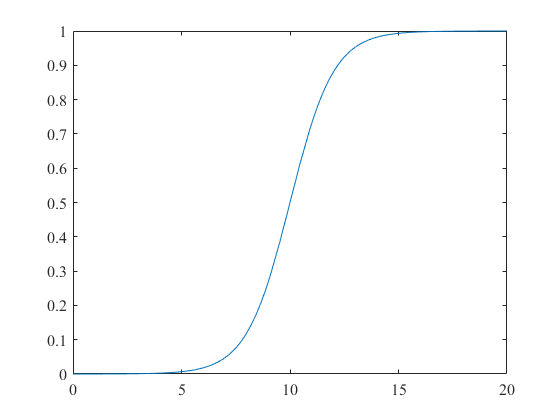

S(t) = 1/(1+exp(-alpha*(t - beta)));
fplot(subs(S(t), [alpha beta], [alpha_ beta_]), [0 20])

Find the maximum value of the derivative to calculate alpha as a function of desired maximum velocity.

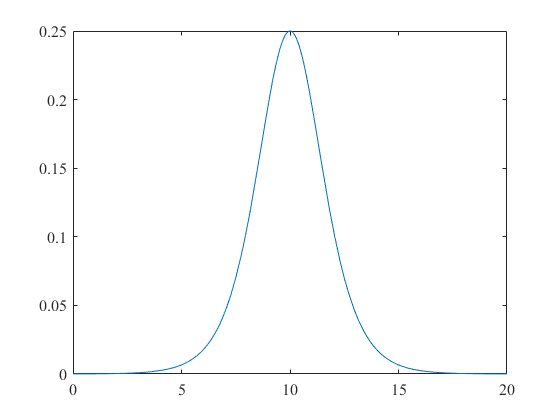

dS(t) = diff(S(t));
fplot(subs(dS(t), [alpha beta], [alpha_ beta_]), [0 20])

The maximum velocity occurs at $t=\beta$

dS(beta)

$$ans = 0.2500\,\alpha$$

Therefore, $v_{\max } =\frac{\alpha }{4}||p_f ||\to \alpha =\frac{\left({4v}_{\max } \right)}{||p_f ||}$  

## Test

dP(t) = dS(t)*P_f;
V_max = subs(dP(beta), alpha, 4*v_max/norm(P_f));
simplify(norm(V_max))

$$ans = \left|v_{\max}\right|$$